clc;
clear;
format shortE;

Taking inputs about elements

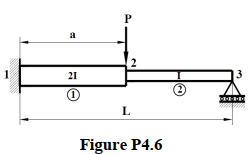

nel=2%input("Enter the number of elements: ");

nel =      2

nnd= nel+1; %Number of nodes
dof=2*nnd; % Degree of freedom for a planar beam
P=12e3

P =        12000

l=[2 2]

l =      2     2


E=200e9

E =    2.0000e+11

mi=0.36e-4*[2 1];

Creating empty global stiffness matrix, force and displacement vector

gstiff=zeros(dof,dof);
gforce=zeros(dof,1);
gdisp=zeros(dof,1);
kel=cell(nel,1);

Calculating global stiffness matrix

for n=1:nel
    i=n;
    j=n+1;
    ix=2*i-1;
    iy=2*i;
    jx=2*j-1;
    jy=2*j;
    %l(n)%=input(sprintf("Enter the length of element %d : ",n));
    L=l(n);
    %el(n)%=input(sprintf("Enter the modulus of elasticity of element %d : ",n));
    %E=el(n);
    %i(n)%=input(sprintf("Enter the moment of inertia for element %d : ",n));
    I=mi(n);
    kel{n}=[12*E*I/L^3 6*E*I/L^2 -12*E*I/L^3 6*E*I/L^2
    6*E*I/L^2 4*E*I/L -6*E*I/L^2 2*E*I/L
    -12*E*I/L^3 -6*E*I/L^2 12*E*I/L^3 -6*E*I/L^2
    6*E*I/L^2 2*E*I/L -6*E*I/L^2 4*E*I/L
    ]
    kel{n}
    gstiff([ix,iy,jx,jy],[ix,iy,jx,jy])=gstiff([ix,iy,jx,jy],[ix,iy,jx,jy])+kel{n};
end

kel = 2×1 cell array
    {4×4 double}
    {0×0 double}

ans =     21600000    21600000   -21600000    21600000
    21600000    28800000   -21600000    14400000
   -21600000   -21600000    21600000   -21600000
    21600000    14400000   -21600000    28800000


kel = 2×1 cell array
    {4×4 double}
    {4×4 double}

ans =     10800000    10800000   -10800000    10800000
    10800000    14400000   -10800000     7200000
   -10800000   -10800000    10800000   -10800000
    10800000     7200000   -10800000    14400000


gstiff

gstiff =     21600000    21600000   -21600000    21600000           0           0
    21600000    28800000   -21600000    14400000           0           0
   -21600000   -21600000    32400000   -10800000   -10800000    10800000
    21600000    14400000   -10800000    43200000   -10800000     7200000
           0           0   -10800000   -10800000    10800000   -10800000
           0           0    10800000     7200000   -10800000    14400000


Applying boundary conditions of externally applied loads

%no_nodes=input("Enter the number of nodes where external force are applied:");
%for u=1:no_nodes
%     prompt=sprintf("Enter the value of node at which external load are applied: ");
%     node=input(prompt);
%     force=sprintf("Enter the external force applied at node %d :",node);
%     gforce(2*node-1)=input(force);
%     moment=sprintf("Enter the external moment applied at node %d :",node);
%     gforce(2*node)=input(moment);
% end
gforce(3)=-P

gforce =            0
           0
      -12000
           0
           0
           0


Calculation of required displacements

g=[3 4 6]%input("Enter the displacements to be found according to their position in the stiffness matrix:");

g =      3     4     6


Extracting the required stiffness matrix

gstiff1=gstiff(g,g)

gstiff1 =     32400000   -10800000    10800000
   -10800000    43200000     7200000
    10800000     7200000    14400000


gforce1=gforce(g)

gforce1 =       -12000
           0
           0


disp1=gstiff1\gforce1;
gdisp(g)=disp1;
gdisp

gdisp =             0
            0
  -6.7901e-04
  -2.7778e-04
            0
   6.4815e-04


force=gstiff*gdisp

force =    8.6667e+03
   1.0667e+04
  -1.2000e+04
            0
   3.3333e+03
   1.8190e-12


Calculation of nodal force

for o=1:nel
    i=o;
    j=o+1;
    ix=2*i-1;
    iy=2*i;
    jx=2*j-1;
    jy=2*j;
    u=gdisp([ix,iy,jx,jy])
    nf{o}=kel{o}*u
end

u =             0
            0
  -6.7901e-04
  -2.7778e-04


nf = 1×1 cell array
    {4×1 double}

u =   -6.7901e-04
  -2.7778e-04
            0
   6.4815e-04


nf = 1×2 cell array
    {4×1 double}    {4×1 double}

gdisp

gdisp =             0
            0
  -6.7901e-04
  -2.7778e-04
            0
   6.4815e-04


force

force =    8.6667e+03
   1.0667e+04
  -1.2000e+04
            0
   3.3333e+03
   1.8190e-12


fprintf("The nodal force vector are: \n")

The nodal force vector are: 


Nodal_force1=nf{1}

Nodal_force1 =    8.6667e+03
   1.0667e+04
  -8.6667e+03
   6.6667e+03


Nodal_force2=nf{2}

Nodal_force2 =   -3.3333e+03
  -6.6667e+03
   3.3333e+03
   1.8190e-12
